close all
clear all

s = tf('s');
F=5*(s+20)/(s*(s^2+2.5*s+2)*(s^2+15*s+100))


F =
 
                   5 s + 100
  --------------------------------------------
  s^5 + 17.5 s^4 + 139.5 s^3 + 280 s^2 + 200 s
 
Continuous-time transfer function.



damp(F) % tipo 1

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00                -1.00e+00       0.00e+00              Inf    
 -1.25e+00 + 6.61e-01i     8.84e-01       1.41e+00         8.00e-01    
 -1.25e+00 - 6.61e-01i     8.84e-01       1.41e+00         8.00e-01    
 -7.50e+00 + 6.61e+00i     7.50e-01       1.00e+01         1.33e-01    
 -7.50e+00 - 6.61e+00i     7.50e-01       1.00e+01         1.33e-01    


Kr = 2;
h = 0;
Kf = dcgain(F * s)

Kf = 0.5000

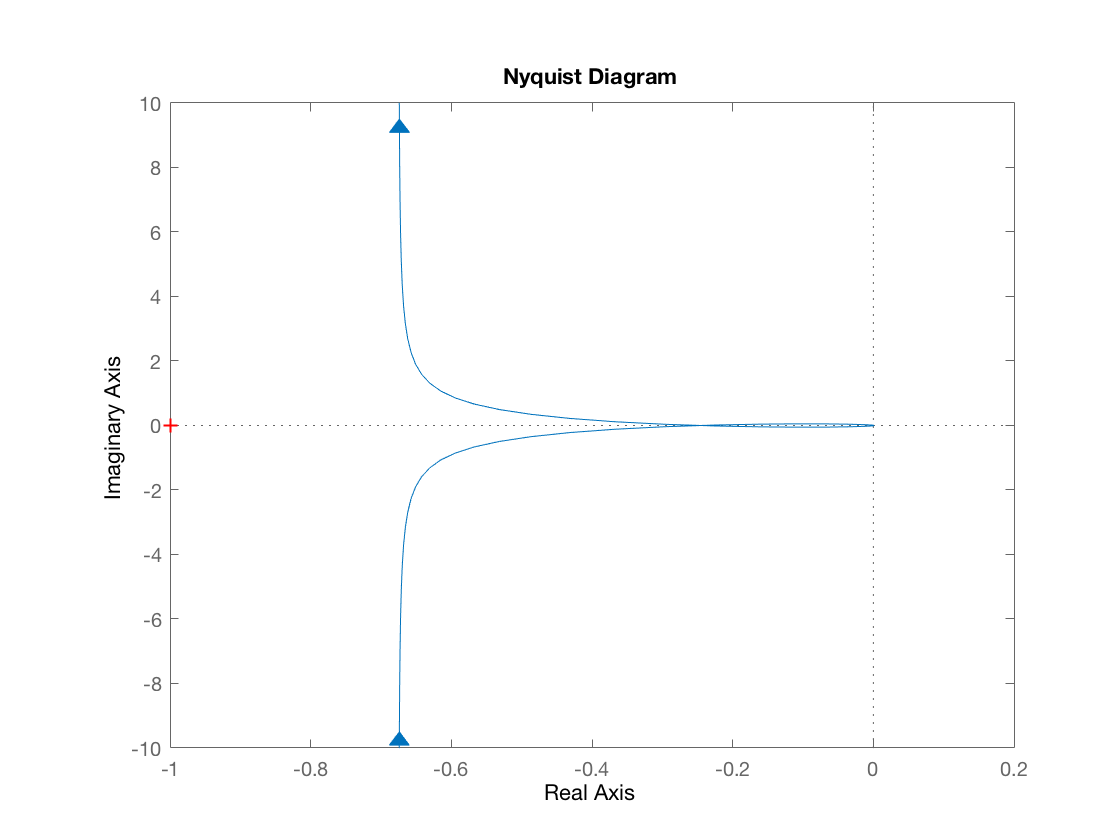

nyquist(F)

Kc > 0

Er_inf = 0.05;
Kc = 20*Kr^2/abs(Kf)

Kc = 160

Ga1 = Kc * F * 1/Kr;
t_s = 1;
w_b = 3/t_s;
w_c_des = 0.63 * w_b

w_c_des = 1.8900

s_max = 0.3;
Mr = (1 + s_max)/0.9;
m_fi_min = 60 - 5 * 20*log10(Mr)

m_fi_min = 44.0299

[mod, fase] = bode(Ga1, w_c_des)

mod = 8.4948

fase = -209.3883

delta_f = m_fi_min - (fase + 180)

delta_f = 73.4182

Rete anticipatrice

m_d = 6;
t_d = 1.25 / w_c_des;
Rd = (1 + t_d * s) / (1 + t_d/m_d * s);
Ga2 = Ga1 * Rd * Rd;
[mod, fase] = bode(Ga2, w_c_des)

mod = 20.8624

fase = -130.2445

Rete integratrice

m_i = 10^(mod/20)

m_i = 11.0439

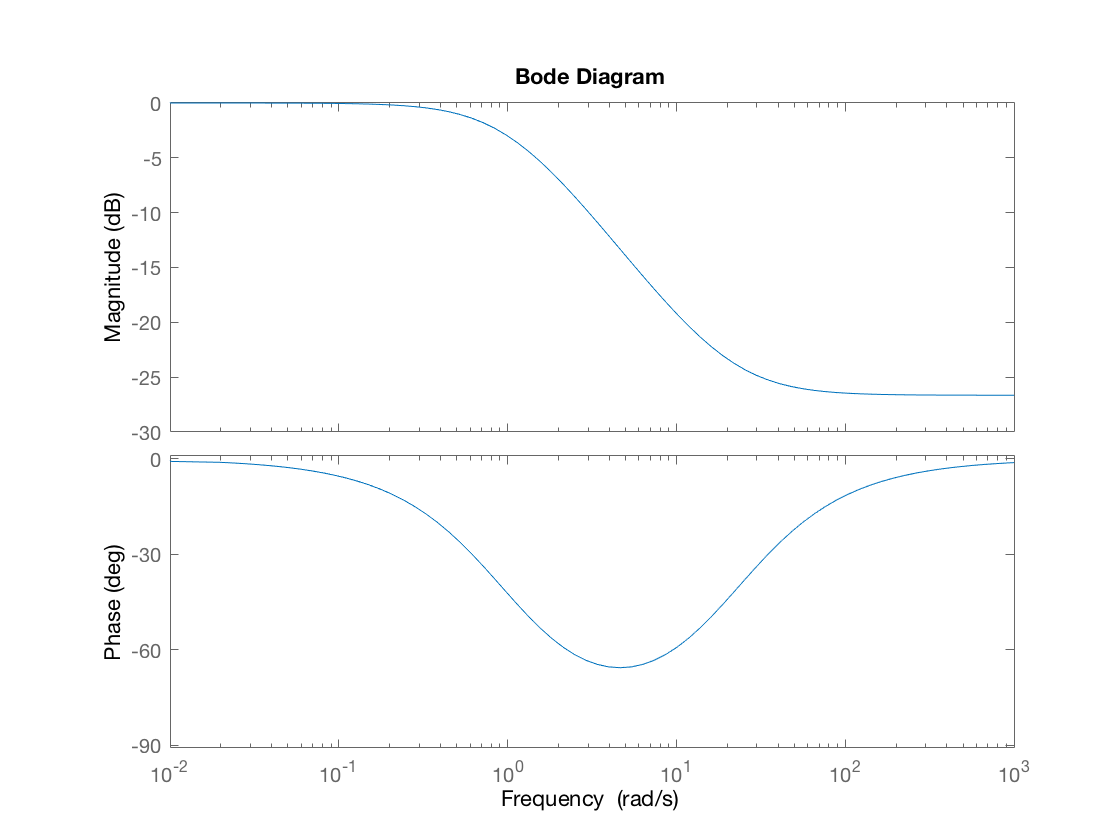

m_i = 21.5;
t_i = 1;
Ri = (1 + t_i/m_i * s) / (1 + t_i * s);
bode(Ri)

x_i = 230;
t_i = x_i / w_c_des;
Ri = (1 + t_i/m_i * s) / (1 + t_i * s);
Ga3 = Ga2 * Ri;
[mod, fase] = bode(Ga3, w_c_des)

mod = 0.9746

fase = -135.3358

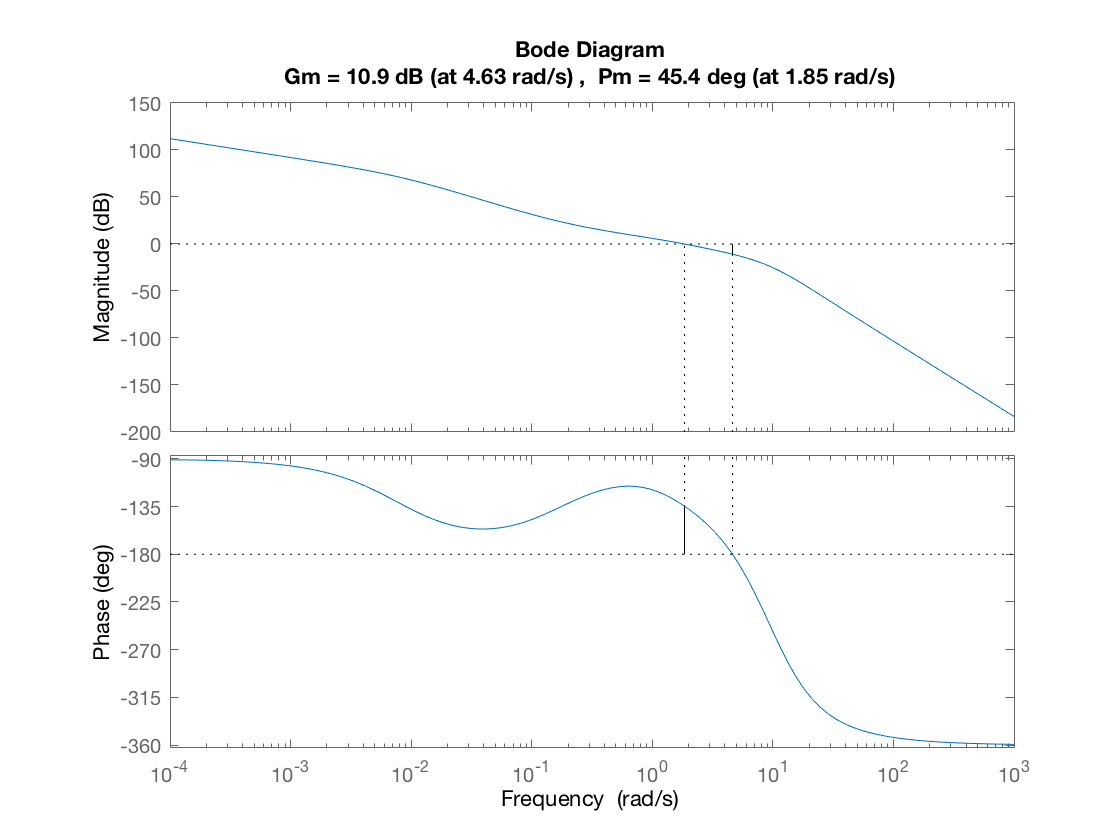

margin(Ga3)

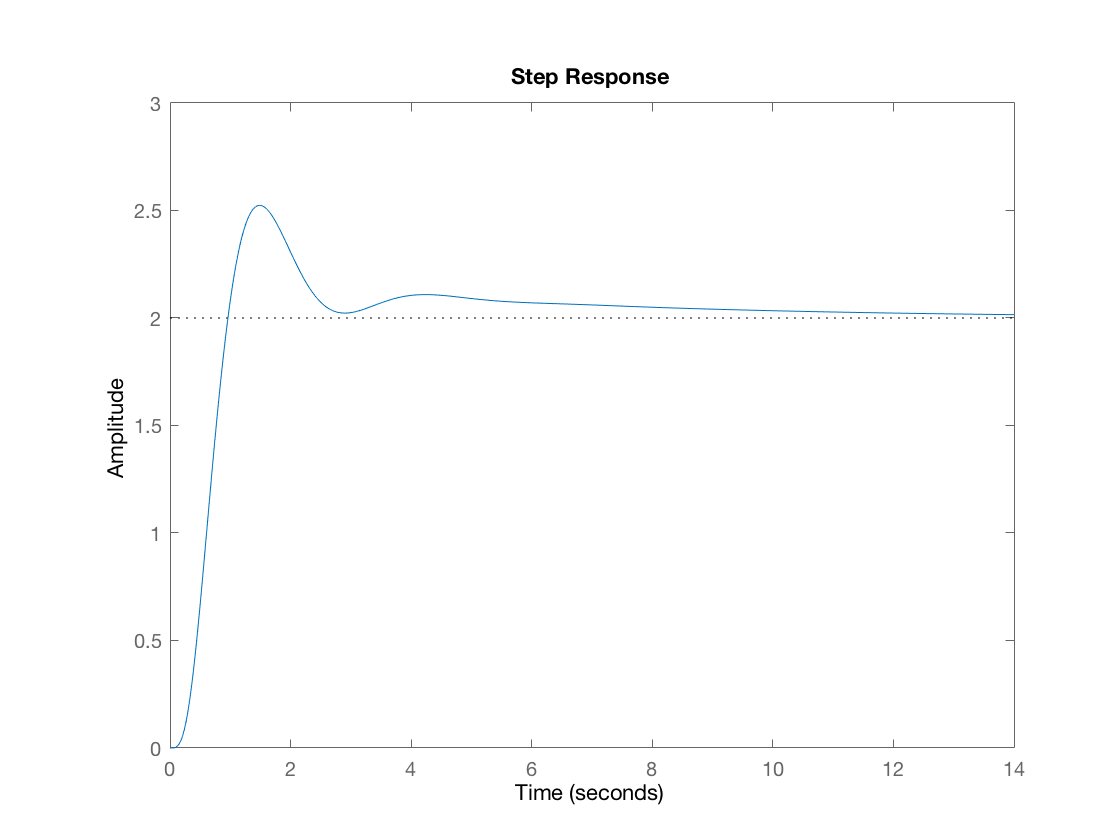

W = feedback(F * Kc * Ri * Rd * Rd, 1/Kr);
step(W)

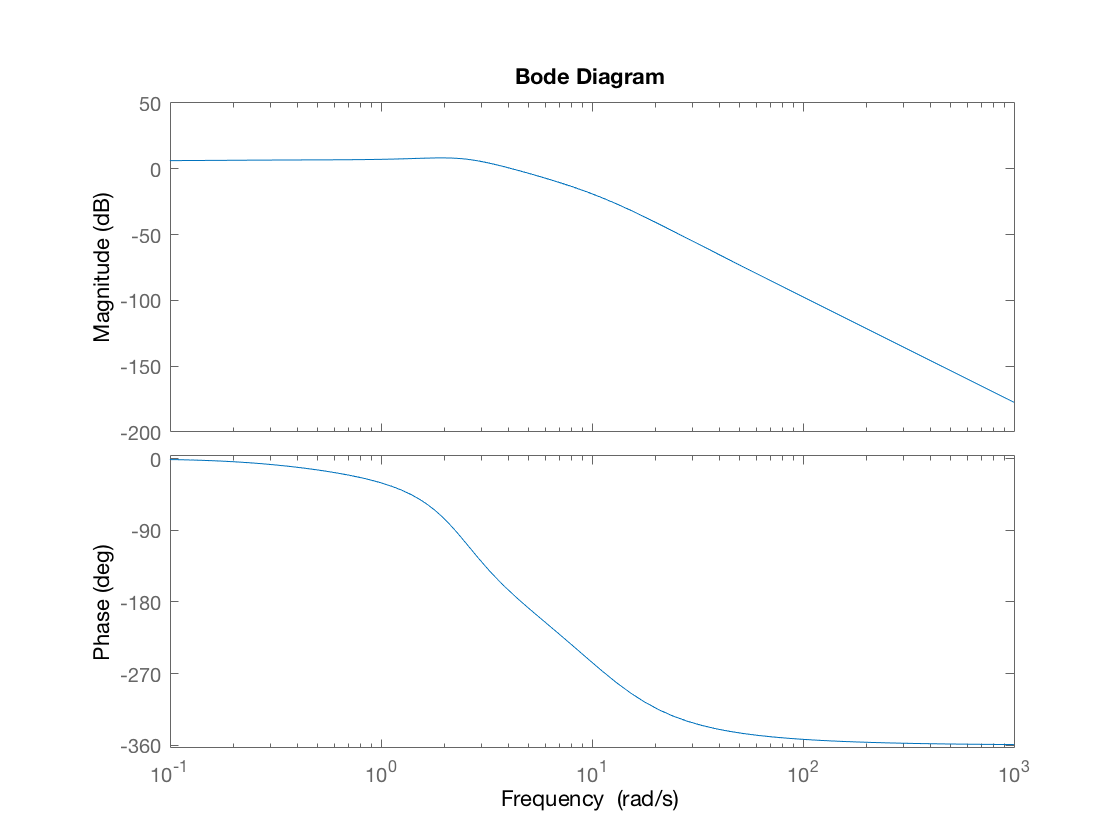

bode(W)